Tensile force calculator. Palm 2.24. Want to find D so that T is minimum

%tension example
W = 400; % Weight of beam in N
Lb = 5; % length of beam in m
Lc = 5;% length of cable in m
D = 0.1:0.1:4.9 % anchor distance

D =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


T = (Lb*Lc*W)./(D.*sqrt(Lc^2.-D.^2))

T = 	1.0e+04 *

    2.0004    1.0008    0.6679    0.5016    0.4020    0.3358    0.2886    0.2533    0.2259    0.2041    0.1864    0.1717    0.1593    0.1488    0.1398    0.1319    0.1251    0.1191    0.1138    0.1091    0.1049    0.1012    0.0979    0.0950    0.0924    0.0901    0.0880    0.0862    0.0847    0.0833    0.0822    0.0813    0.0807    0.0802    0.0800    0.0801    0.0804    0.0810    0.0819    0.0833    0.0852    0.0878    0.0911    0.0957    0.1020    0.1109    0.1247    0.1488    0.2051


You can plot D vs T to visualize the minimum:

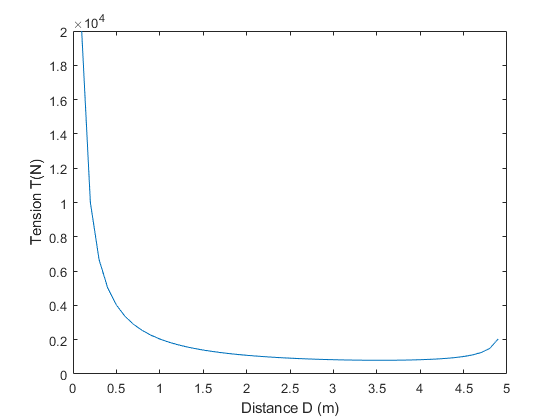

plot(D,T)
xlabel('Distance D (m)')
ylabel('Tension T(N)')

Now use the *min *function to find the minimum inside the array T, and index of this minimum:

[Tmin,minidx]=min(T)% 800.16

Tmin = 800.1600

minidx = 35

Then, the minimum distance is given by D(minidx):

Dmin = D(minidx) % 3.5 is the distance that minimizes T

Dmin = 3.5000

Find the indexes of D that result in T within 10% of the minimum value:

in = find(T < 1.1*Tmin) % values of D

in =     27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42


D(in)

ans =     2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000


Different types of arrays: Cell Arrays. Cell Arrays can store different information in each array.

%%Different ways to do a cell%%
A = cell(2,2) % 2 by 2 cell array.

A = 2×2 cell array
    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}


A(1,1) = {'Nuese River Basin'} % cell indexing

A = 2×2 cell array
    {'Nuese River Basin'}    {0×0 double}
    {0×0 double         }    {0×0 double}


A{1,2} = 'Jan 10, 2005' % content indexing

A = 2×2 cell array
    {'Nuese River Basin'}    {'Jan 10, 2005'}
    {0×0 double         }    {0×0 double    }


A(2,1) = {[50 60 58]}

A = 2×2 cell array
    {'Nuese River Basin'}    {'Jan 10, 2005'}
    {1×3 double         }    {0×0 double    }


A{2,2} = [45 47 46;
          44 46 45; 
          42 45 43]

A = 2×2 cell array
    {'Nuese River Basin'}    {'Jan 10, 2005'}
    {1×3 double         }    {3×3 double    }



B  = {'Nuese River Basin', 'Jan 10,2005';
    [50 60 58], [45 47 46;44 46 45; 42 45 43]}

B = 2×2 cell array
    {'Nuese River Basin'}    {'Jan 10,2005'}
    {1×3 double         }    {3×3 double   }


You can display and plot the cells: 

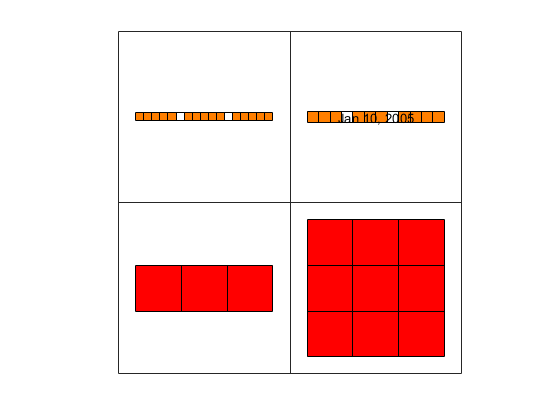

cellplot(A) % plot

celldisp(A) % dislay all cells in the command line

 
A{1,1} =
 
Nuese River Basin
 
 
A{2,1} =
 
    50    60    58

 
 
A{1,2} =
 
Jan 10, 2005
 
 
A{2,2} =
 
    45    47    46
    44    46    45
    42    45    43

 


Cell array exercise 1 Palm 2.61 p.119:

C = cell(2);
C(1,1) = {'Motor 28C'}; % cell indexing
C{1,2} = 'Test ID 6'; % content indexing
C(2,1) = {[3 9;7 2]} % cell indexing

C = 2×2 cell array
    {'Motor 28C'}    {'Test ID 6'}
    {2×2 double }    {0×0 double }


C{2,2} = [6 5 1]; % content indexing
celldisp(C) % show all entries of cell array C

 
C{1,1} =
 
Motor 28C
 
 
C{2,1} =
 
     3     9
     7     2

 
 
C{1,2} =
 
Test ID 6
 
 
C{2,2} =
 
     6     5     1

 


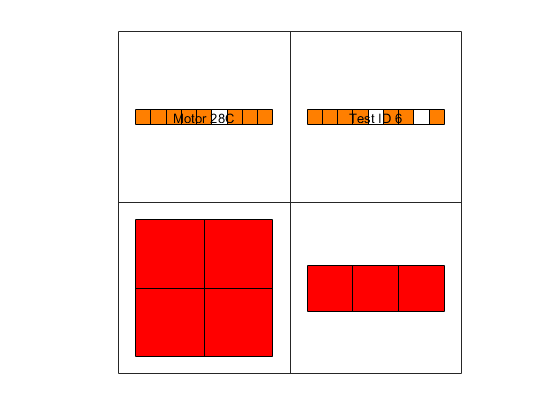

cellplot(C)

Cell array exercises 2.62. Capacitance of two parallel conductors of length L and radius r separated by a distance d in air is given by:

d = [0.003 0.004 0.005 0.001]; % distance
L = [1 2 3]; % length in meters
r = [0.001 0.002 0.003]; %radius
epsilon = 8.854*10^(-12);
A2 = cell(2,4); % 2 rows 4 columns cell array
A{1,1} = 'd, distance'; % content indexing
A{1,2} = 'L,length';
A{1,3} = 'r,radius';
A{1,4} = 'C,capacitance';

A(2,1) = {d};% length 4
A(2,2) = {L}% length 3

A = 2×4 cell array
    {'d, distance'}    {'L,length'}    {'r,radius'}    {'C,capacitance'}
    {1×4 double   }    {1×3 double}    {0×0 double}    {0×0 double     }


A(2,3) = {r}%length 3

A = 2×4 cell array
    {'d, distance'}    {'L,length'}    {'r,radius'}    {'C,capacitance'}
    {1×4 double   }    {1×3 double}    {1×3 double}    {0×0 double     }


C=zeros(4,3,3);% good for performance
for i=1:4
    for j=1:3
        for k=1:3
            C(i,j,k) = (pi*epsilon*L(j))/(log((d(i)- r(k))/r(k)));
        end
    end
end
A{2,4}= C

A = 2×4 cell array
    {'d, distance'}    {'L,length'}    {'r,radius'}    {'C,capacitance'}
    {1×4 double   }    {1×3 double}    {1×3 double}    {4×3×3 double   }
